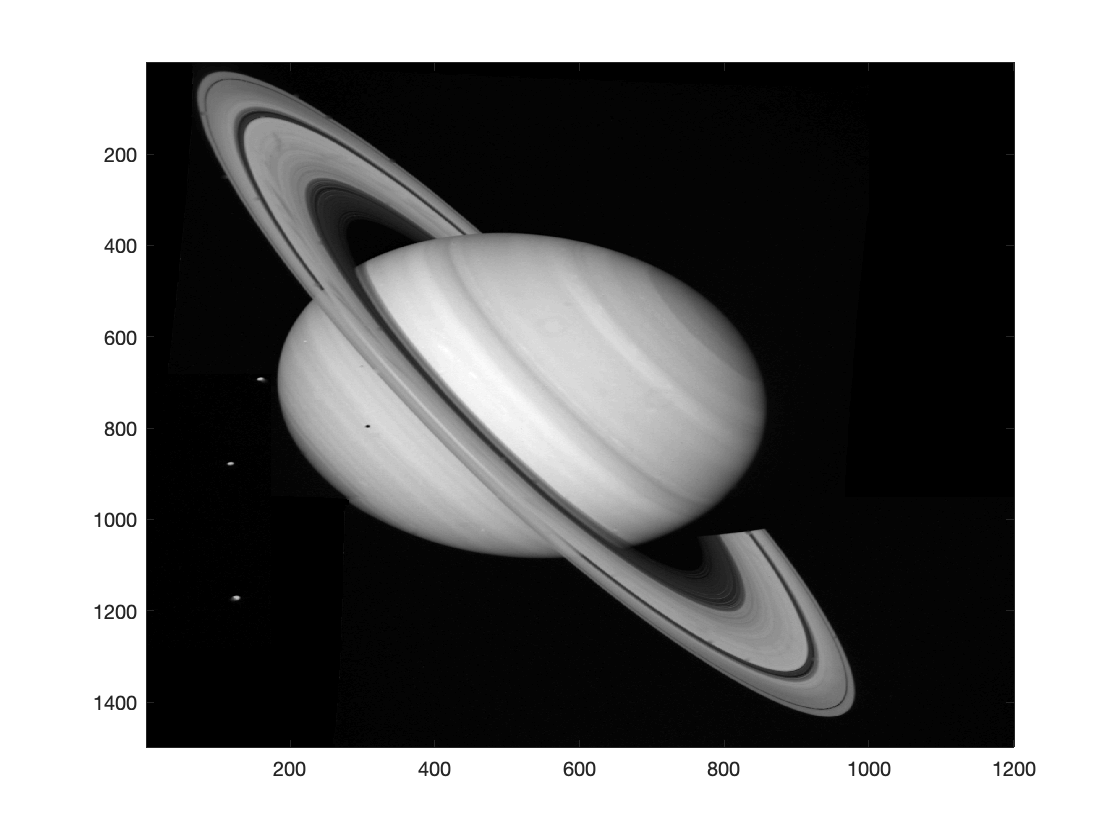

f = imread('saturn.png');
fr = f(:,:,1:1);
figure(1)
imagesc(fr)
colormap(gray)

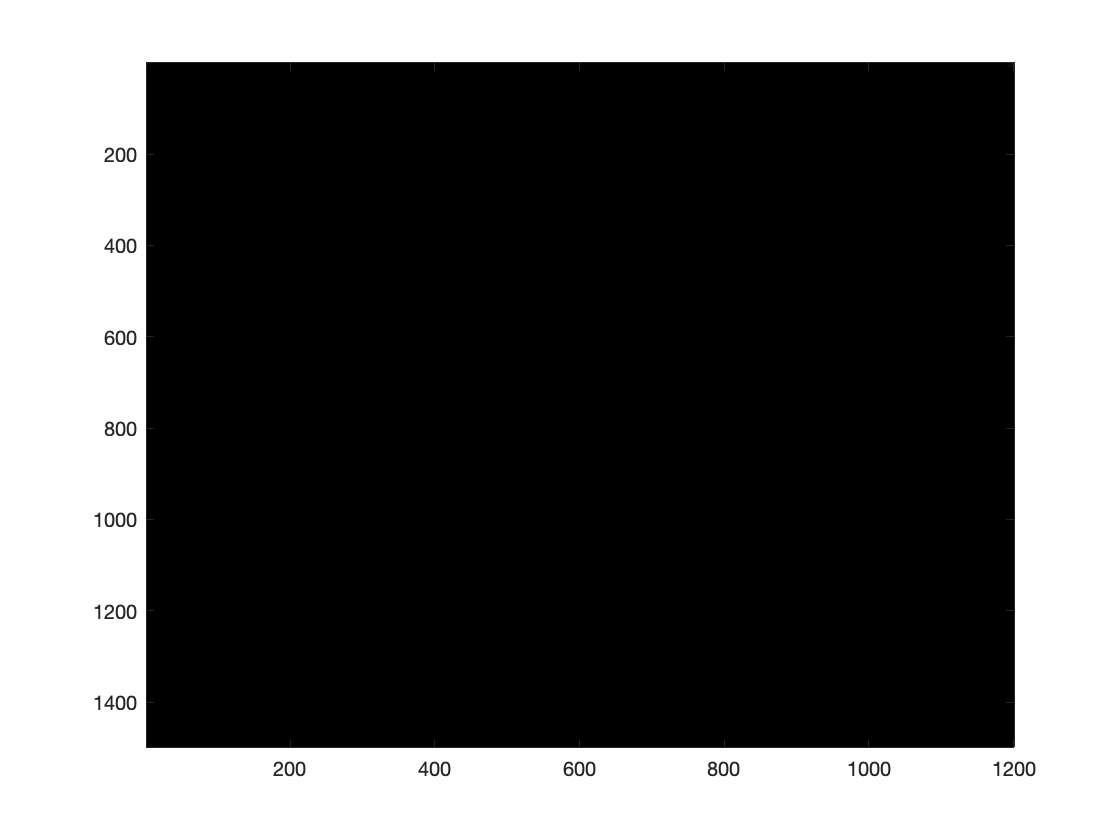


F = fft2(fr);
Re = real(F);
Im = imag(F);
Spectre = abs(F);
figure(2)
imagesc(Spectre)
colormap(gray)


min(min(Spectre))

ans = 1.3871

max(max(Spectre))

ans = 78232008

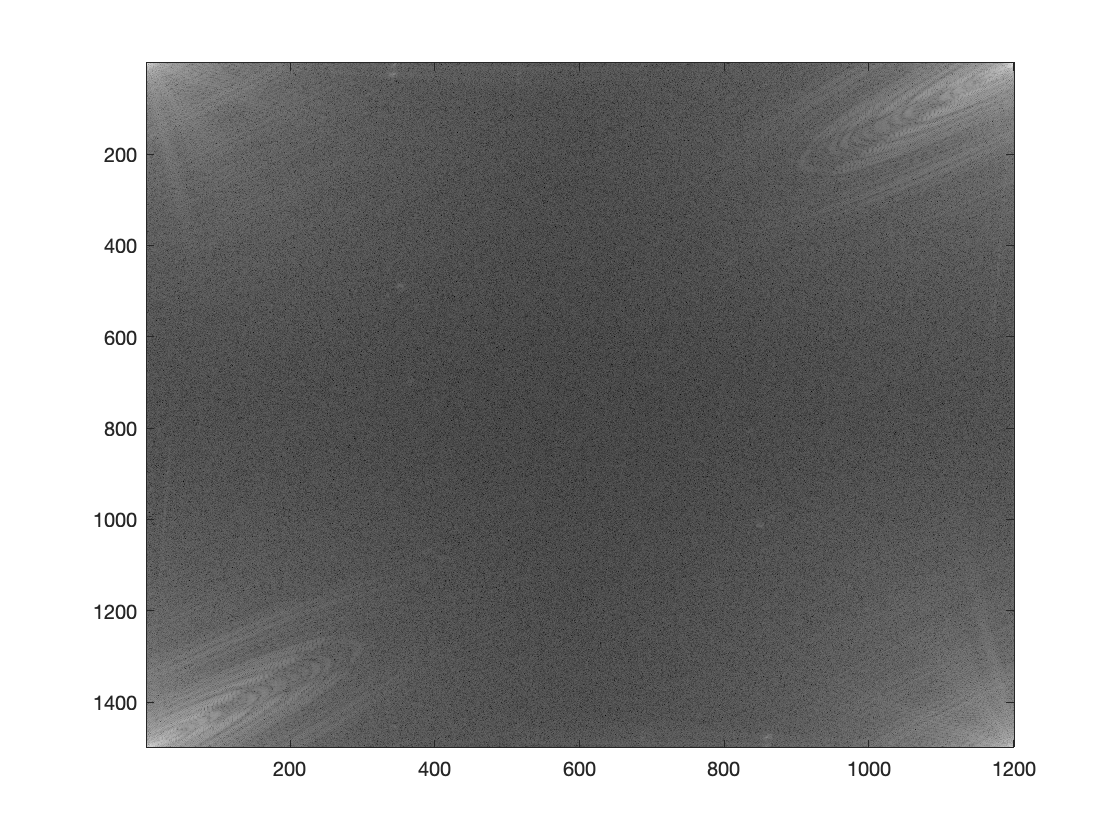


figure(3)
imagesc(log(1+Spectre))
colormap(gray)

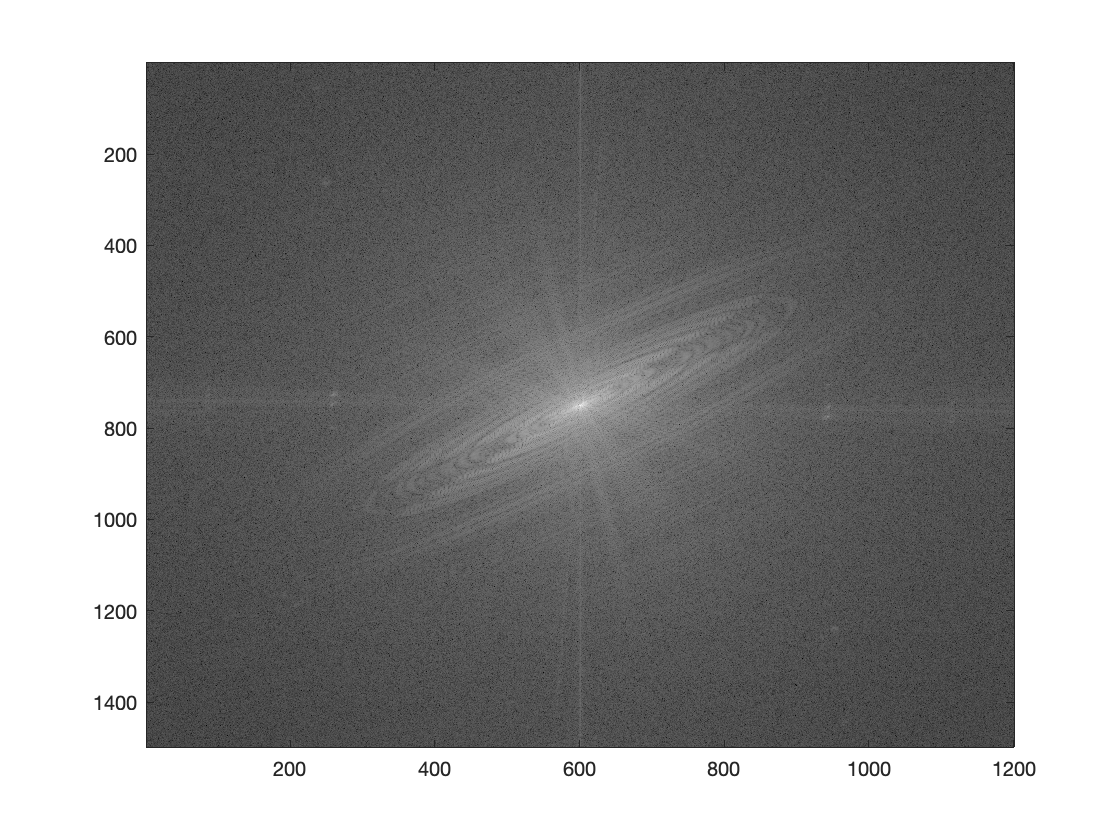


figure(4)
imagesc(log(1+fftshift(Spectre)))
colormap(gray)

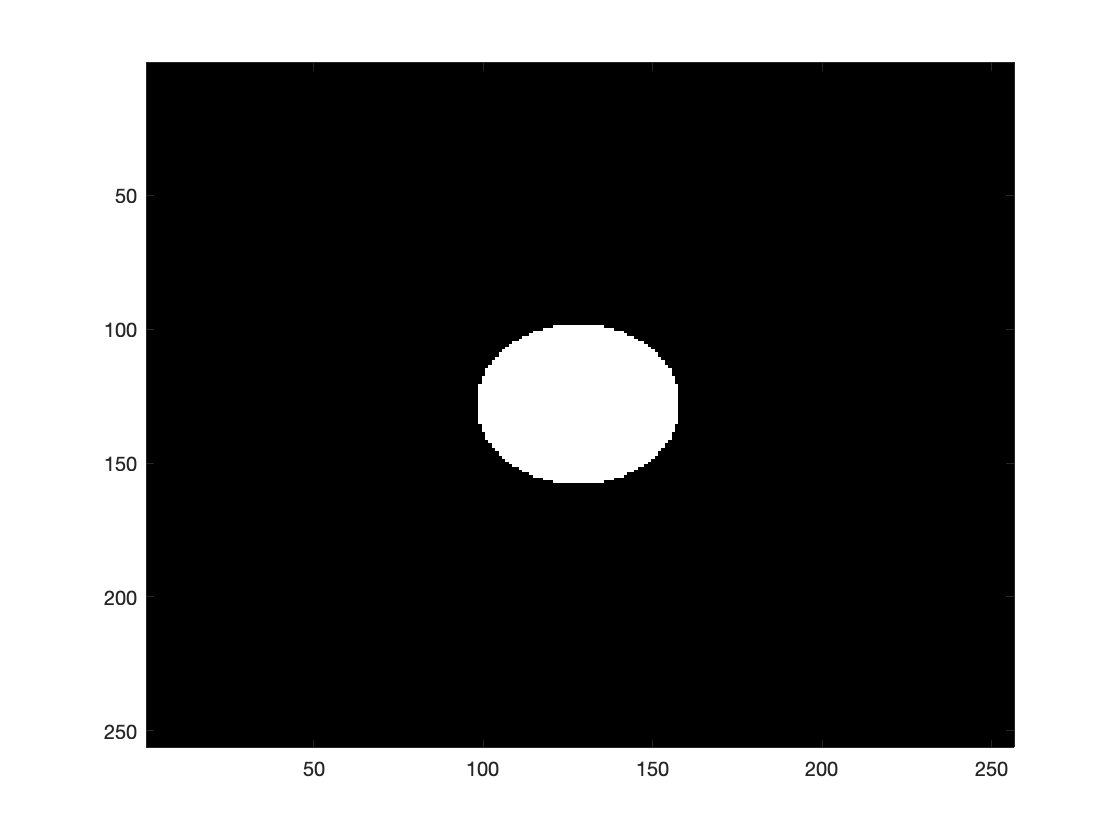

%Convolution avec FFT

f = imread('cameraman.tif');
F = fft2(f);
H = zeros(256);
for i = 1:256
    for j = 1:256
       p = sqrt((i-128)*(i-128) + (j-128)*(j-128));
       if p < 30   %freq de coupure (rayon du cercle)
           H(i,j) = 1/30;
       end
    end
end
figure(5)
imagesc(H)

colormap(gray)

Fshift = fftshift(F);
G = Fshift .* H;
Gshift = fftshift(G);
g = ifft2(Gshift);
greel = real(g);

min(min(greel))

ans = -0.7320

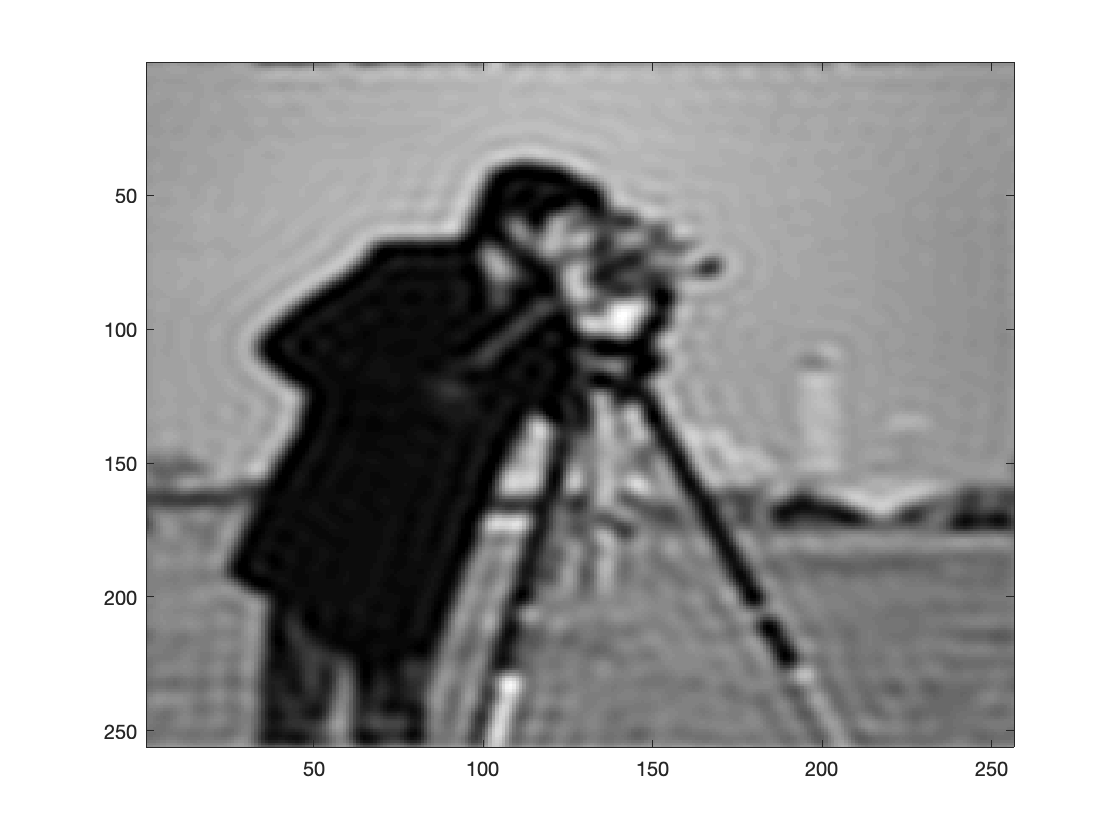


gpos = (greel > 0).*greel;

figure(6)
imagesc(gpos)

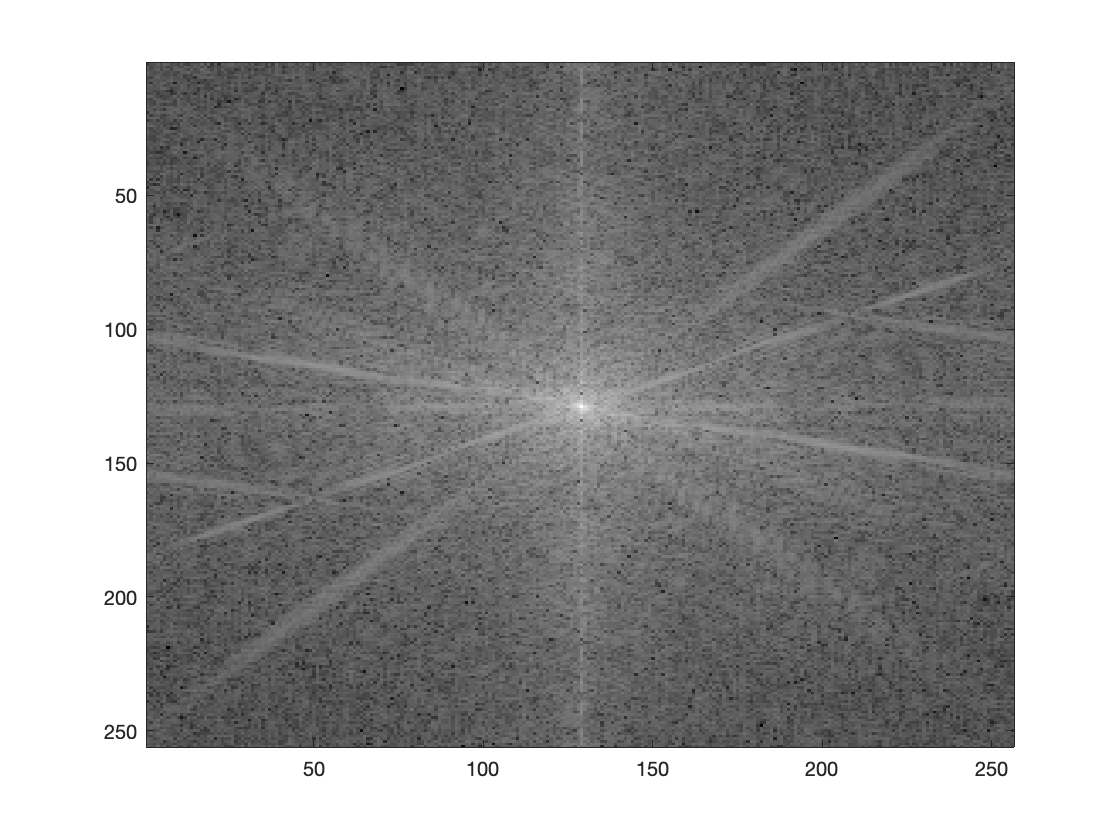

colormap(gray)

figure(7)
imagesc(log(1 + abs(Fshift)))

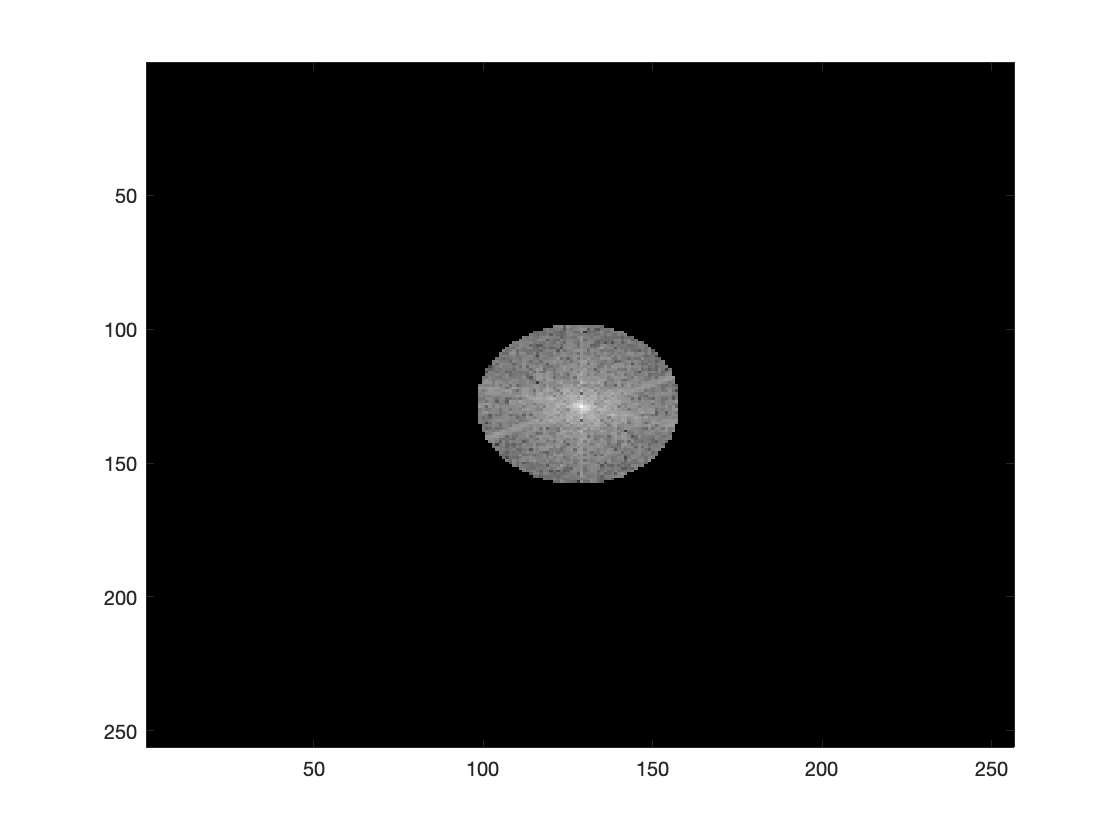

colormap(gray)



figure(8)
imagesc(log(1 + abs(G)))
colormap(gray)